# Assignment 2

## 1 How finite should it be?

### 1.1 Like a hot knife through a Butterworth

In the following we atempt to construct an FIR bandpass filter which meets the following specifications (normalized frequency): 

- Passband from 0.2 to 0.3. 

- Stopbands from 0 to 0.1 and 0.4 to 1

- Ripples are OK if they don't exceed 2 dB

- The stopband attenuation should be at least -100 dB

clear all; clc;

% Filter specifications
Wp = [0.2 0.3]; % Passband corner frequencies
Ws = [0.1 0.4]; % Stopband corner frequencies
Rp = 2;         % Maximum ripple amplitude
Rs = -100;      % Stopband attenuation

% Butterworth bandpass filter design
[N_bw,Wn_bw] = buttord(Wp,Ws,Rp,-Rs);
[B_bw,A_bw] = butter(N_bw,Wn_bw,"bandpass");

% Chebychev I bandpass filter design
[N_ch1,Wn_ch1] = cheb1ord(Wp,Ws,Rp,-Rs);
[B_ch1,A_ch1] = cheby1(N_ch1,Rp,Wn_ch1,"bandpass");

% Chebychev II bandpass filter design
[N_ch2,Wn_ch2] = cheb1ord(Wp,Ws,Rp,Rs);
[B_ch2,A_ch2] = cheby2(N_ch2,-Rs,Wn_ch2,"bandpass");

% Elliptical bandpass filter design
[N_ep,Wn_ep] = ellipord(Wp,Ws,Rp,-Rs);
[B_ep,A_ep] = ellip(N_ep,Rp,-Rs,Wn_ep,"bandpass");

% Frequency responses of four different filters with same specifications
figure("Name", "FR")
subplot(2,1,1)

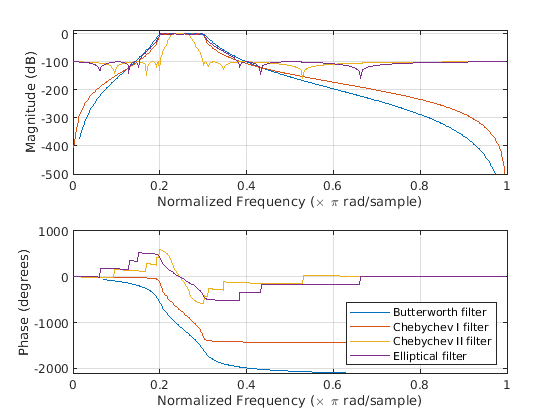

[H_bw,W] = freqz(B_bw,A_bw);
[H_ch1,~] = freqz(B_ch1,A_ch1);
[H_ch2,~] = freqz(B_ch2,A_ch2);
[H_ep,~] = freqz(B_ep,A_ep);
plot(W/pi,20*log10(abs(H_bw))), hold on;
plot(W/pi,20*log10(abs(H_ch1))), hold on;
plot(W/pi,20*log10(abs(H_ch2))), hold on;
plot(W/pi,20*log10(abs(H_ep))), hold off
grid on
ylim([-500 10])
xlabel("Normalized Frequency (\times \pi rad/sample)")
ylabel("Magnitude (dB)")
subplot(2,1,2)
[phi_bw,~] = phasez(B_bw,A_bw);
[phi_ch1,~] = phasez(B_ch1,A_ch1);
[phi_ch2,~] = phasez(B_ch2,A_ch2);
[phi_ep,~] = phasez(B_ep,A_ep);
plot(W/pi,phi_bw*180/pi), hold on;
plot(W/pi,phi_ch1*180/pi), hold on;
plot(W/pi,phi_ch2*180/pi), hold on;
plot(W/pi,phi_ep*180/pi), hold off
grid on
xlabel("Normalized Frequency (\times \pi rad/sample)")
ylabel("Phase (degrees)")
legend(["Butterworth filter","Chebychev I filter","Chebychev II filter","Elliptical filter"],"Location","southeast")
saveas(gcf,"plots/filter_types_freq_resp","png");

In the following, we choose to pursue the Butterworth filter design, as it provides a flat passband gain with sufficient stopband attenuation. 

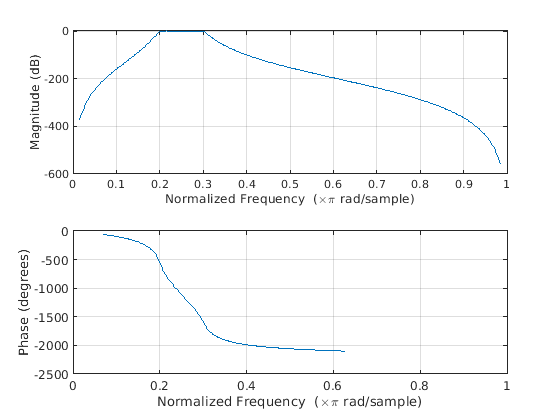

  Column 1

    0.1986

  Column 2

    0.3020



% Frequency response
freqz(B_bw,A_bw); disp(Wn_bw)

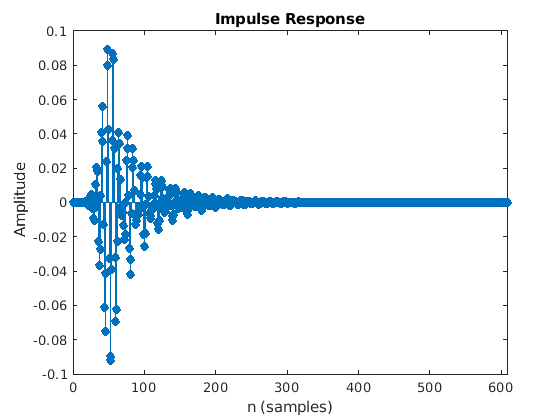

% Impulse response
impz(B_bw,A_bw);

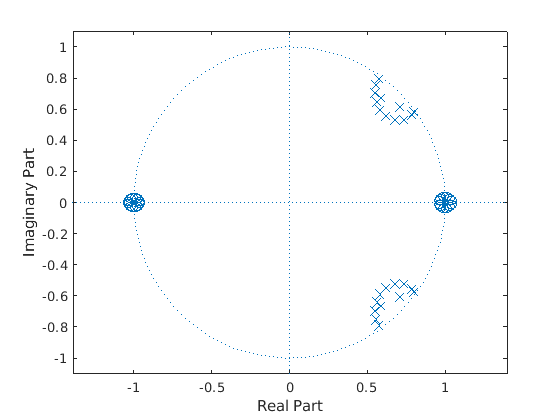

% z-plane plot
zplane(B_bw,A_bw)

Now take the impulse response. Let’s define for practical reasons an effective length of the impulse response the length (in samples) at which the impulse response decays below a value of 10% of its maximum. Now vary the length of the filter:

- Cut the filter at its effective length

- Cut the filter to 75%/60%/40%/10% of its effective length

and compare the frequency response of the resulting filters by plotting them on top of each other. Use a rectangular window and one other window of your choice. Describe what happens to the frequency response when the impulse responses are shortened. 

% Get the impulse response of the Butterworth filter
[h,t] = impz(B_bw,A_bw);

% Find the effective length of the impulse response, where h > 10% of max(H)
el = find(h > 0.1*max(h), 1, "last");

% Cut the filter to 100%/75%/60%/40%/10% of its effective length using a
% rectangular window
h_el_rect   = rectwin(el).*h(1:el);
h_75el_rect = [rectwin(fix(.75*el)).*h(1:fix(.75*el)); zeros(fix(.25*el),1)];
h_60el_rect = [rectwin(fix(.60*el)).*h(1:fix(.60*el)); zeros(fix(.40*el),1)];
h_40el_rect = [rectwin(fix(.40*el)).*h(1:fix(.40*el)); zeros(fix(.60*el),1)];
h_10el_rect = [rectwin(fix(.10*el)).*h(1:fix(.10*el)); zeros(fix(.90*el),1)];

% ... and a Hann window
h_el_hann   = hann(el).*h(1:el);
h_75el_hann = [hann(fix(.75*el)).*h(1:fix(.75*el)); zeros(fix(.25*el),1)];
h_60el_hann = [hann(fix(.60*el)).*h(1:fix(.60*el)); zeros(fix(.40*el),1)];
h_40el_hann = [hann(fix(.40*el)).*h(1:fix(.40*el)); zeros(fix(.60*el),1)];
h_10el_hann = [hann(fix(.10*el)).*h(1:fix(.10*el)); zeros(fix(.90*el),1)];

% Fourier transform the impulse response to get the filters' frequency response
H_el_rect   = fft(h_el_rect); H_el_rect = H_el_rect(1:ceil(length(h_el_rect)/2));
H_75el_rect = fft(h_75el_rect); H_75el_rect = H_75el_rect(1:ceil(length(H_75el_rect)/2));
H_60el_rect = fft(h_60el_rect); H_60el_rect = H_60el_rect(1:ceil(length(H_60el_rect)/2));
H_40el_rect = fft(h_40el_rect); H_40el_rect = H_40el_rect(1:ceil(length(H_40el_rect)/2));
H_10el_rect = fft(h_10el_rect); H_10el_rect = H_10el_rect(1:ceil(length(H_10el_rect)/2));
H_el_hann   = fft(h_el_hann); H_el_hann = H_el_hann(1:ceil(length(h_el_hann)/2));
H_75el_hann = fft(h_75el_hann); H_75el_hann = H_75el_hann(1:ceil(length(H_75el_hann)/2));
H_60el_hann = fft(h_60el_hann); H_60el_hann = H_60el_hann(1:ceil(length(H_60el_hann)/2));
H_40el_hann = fft(h_40el_hann); H_40el_hann = H_40el_hann(1:ceil(length(H_40el_hann)/2));
H_10el_hann = fft(h_10el_hann); H_10el_hann = H_10el_hann(1:ceil(length(H_10el_hann)/2));

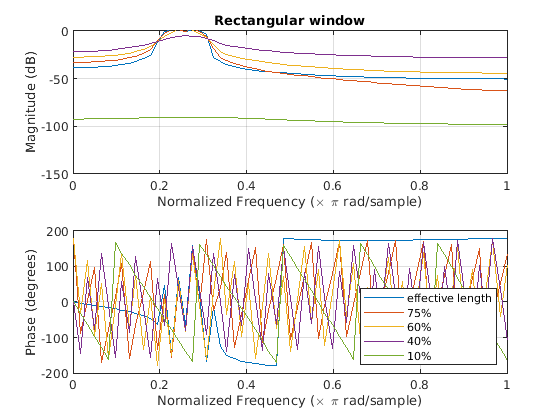

% Plot the frequency responses at different filter lengths
figure("Name", "Frequency response at different effective lengths")
f = linspace(0,1,length(H_el_rect)); % Frequency vector for plotting
subplot(2,1,1)
plot(f, 20*log10(abs(H_el_rect))), hold on;
plot(f, 20*log10(abs(H_75el_rect))), hold on;
plot(f, 20*log10(abs(H_60el_rect))), hold on;
plot(f, 20*log10(abs(H_40el_rect))), hold on;
plot(f, 20*log10(abs(H_10el_rect))), hold off
grid on
ylim([-150 0])
xlabel("Normalized Frequency (\times \pi rad/sample)")
ylabel("Magnitude (dB)")
title("Rectangular window")
subplot(2,1,2)
plot(f, rad2deg(angle(H_el_rect))), hold on;
plot(f, rad2deg(angle(H_75el_rect))), hold on;
plot(f, rad2deg(angle(H_60el_rect))), hold on;
plot(f, rad2deg(angle(H_40el_rect))), hold on;
plot(f, rad2deg(angle(H_10el_rect))), hold off
grid on
xlabel("Normalized Frequency (\times \pi rad/sample)")
ylabel("Phase (degrees)")
legend(["effective length", "75%", "60%", "40%", "10%"],"Location", "southeast");
saveas(gcf,"plots/eff_length_freq_resp_rect_window","png");

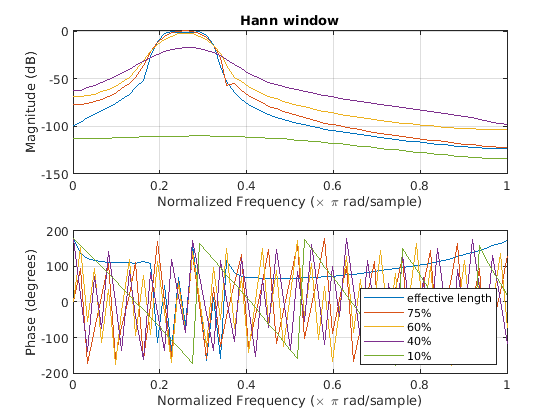

figure("Name", "Frequency response at different effective lengths using Hann window")
subplot(2,1,1)
plot(f, 20*log10(abs(H_el_hann))), hold on;
plot(f, 20*log10(abs(H_75el_hann))), hold on;
plot(f, 20*log10(abs(H_60el_hann))), hold on;
plot(f, 20*log10(abs(H_40el_hann))), hold on;
plot(f, 20*log10(abs(H_10el_hann))), hold off
grid on
xlabel("Normalized Frequency (\times \pi rad/sample)")
ylabel("Magnitude (dB)")
title("Hann window")
subplot(2,1,2)
plot(f, rad2deg(angle(H_el_hann))), hold on;
plot(f, rad2deg(angle(H_75el_hann))), hold on;
plot(f, rad2deg(angle(H_60el_hann))), hold on;
plot(f, rad2deg(angle(H_40el_hann))), hold on;
plot(f, rad2deg(angle(H_10el_hann))), hold off
grid on
xlabel("Normalized Frequency (\times \pi rad/sample)")
ylabel("Phase (degrees)")
legend(["effective length", "75%", "60%", "40%", "10%"],"Location", "southeast");
saveas(gcf,"plots/eff_length_freq_resp_hann_window","png");

### 1.2 Shorter and shorter

For an application you are to construct a FIR lowpass filter by the frequency domain equivalence, i.e. by sampling the frequency response of a perfect lowpass filter. You got a sheet of paper from you colleague that holds the specs: The filter passes all frequencies between 0 and 5 kHz with a gain af 0 dB. Just over the sampling frequency, there is this huge coffee stain, making it impossible to read, the same for the order of the desired filter. But you see from the sketch that the cutoff of the filter corresponds to one third on a normalized frequency axis, and you can see that the impulse response should be 601 samples long. 

- Which sampling rate should you use? 

- Construct the filter and plot the frequency and the impulse response

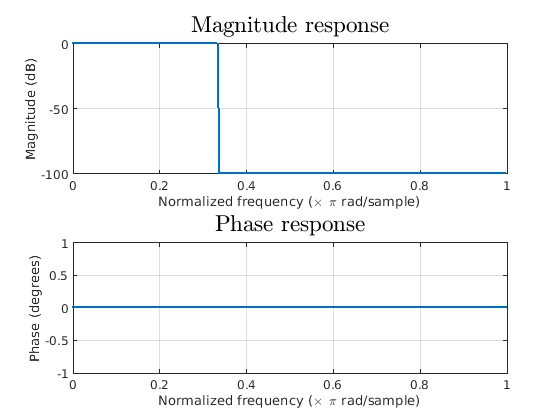

fs = 30e3;  % Sampling frequency
fn = fs/2;  % Nyquist frequency
L = 601;    % Length of impulse response
T = L/fs; % Duration of impulse response
df = 1/T;
f = 0:df:fn; % Frequency vector
Y = [ones(1,ceil(length(f)/3)) 1e-5*ones(1,floor(2*length(f)/3))];
f = [-flip(f) f(2:end)];
Y = [flip(Y) Y(2:end)];  % Make Y two-sided centered around 0 Hz

% Frequency response of the idealized low-pass filter
figure("Name", "Frequency response")
subplot(2,1,1)
plot(f/fn,20*log10(abs(Y)), "LineWidth", 2)
grid on
xlim([0 1]) % Only plot positive frequencies
xlabel("Normalized frequency (\times \pi rad/sample)")
ylabel("Magnitude (dB)")
title("Magnitude response",'Interpreter',"latex",'FontSize', 17);
subplot(2,1,2);
plot(f,angle(Y)*180/pi, "LineWidth", 2);
grid on
xlim([0 1])
xlabel("Normalized frequency (\times \pi rad/sample)")
ylabel("Phase (degrees)")
title("Phase response",'Interpreter',"latex",'FontSize', 17);
set(gcf, 'PaperPosition', [0 0 5 5]); %Position plot at left hand corner with width 5 and height 5.
set(gcf, 'PaperSize', [5 5]);
saveas(gcf, "plots/freq_resp_lowpass_fir", "pdf")

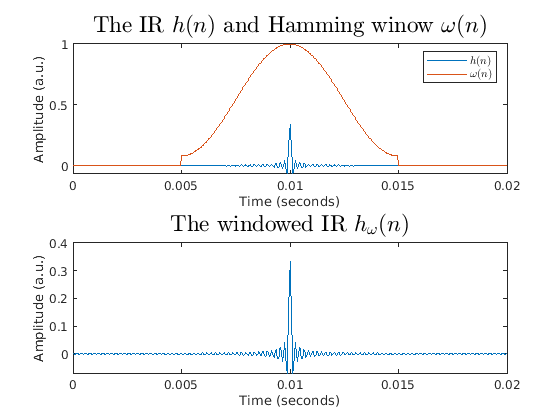

% Impulse response
h = ifft(ifftshift(Y));
t = 0:1/fs:T-1/fs; 
% Time shift the impulse response to make it causal, and multiply it by
% a 50% Hamming window
w = [zeros(1,0.005*fs) hamming(0.01*fs)' zeros(1,0.005*fs+1)];
w_sig = w.*fftshift(h);

% Plot time-shifted impulse response on top of Hamming window
figure("Name", "Impulse response and window function");
subplot(2,1,1)
plot(t,fftshift(h)), hold on;
plot(t,w), hold off
xlabel("Time (seconds)")
ylabel("Amplitude (a.u.)")
title("The IR $h(n)$ and Hamming winow $\omega(n)$",'Interpreter',"latex",'FontSize', 17);
legend(["$h(n)$", "$\omega(n)$"], "Interpreter", "latex", "Location", "northeast");
subplot(2,1,2)
plot(t,fftshift(h))
xlabel("Time (seconds)")
ylabel("Amplitude (a.u.)")
title("The windowed IR $h_{\omega}(n)$",'Interpreter',"latex",'FontSize', 17);
set(gcf, 'PaperPosition', [0 0 5 4]); 
set(gcf, 'PaperSize', [5 4]);
saveas(gcf,"plots/impulse_resp_lowpass_fir_window", "pdf")

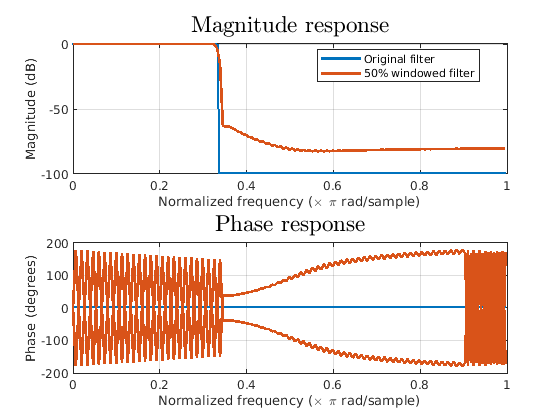

% Frequency spectrum
Y2 = fftshift(fft(w_sig(0.005*fs:0.015*fs)));
T = length(Y2)/fs; 
delta_f = 1/T; 
f2 = 0:delta_f:fn; 
f2 = [flip(f2) f2(2:end)]; 

% Frequency response
figure("Name", "Frequency response")
subplot(2,1,1)
plot(f/fn,20*log10(abs(Y)), "LineWidth", 2), hold on;
plot(f2/fn,20*log10(abs(Y2)), "LineWidth", 2), hold off
grid on
xlim([0 1])
xlabel("Normalized frequency (\times \pi rad/sample)")
ylabel("Magnitude (dB)")
legend(["Original filter", "50% windowed filter"], "Location", "best")
title("Magnitude response",'Interpreter',"latex",'FontSize', 17);
subplot(2,1,2);
plot(f/fn,angle(Y)*180/pi, "LineWidth", 2), hold on;
plot(f2/fn,angle(Y2)*180/pi, "LineWidth", 2), hold off
grid on
xlim([0 1])
xlabel("Normalized frequency (\times \pi rad/sample)")
ylabel("Phase (degrees)")
title("Phase response",'Interpreter',"latex",'FontSize', 17);
set(gcf, 'PaperPosition', [0 0 5 5]); %Position plot at left hand corner with width 5 and height 5.
set(gcf, 'PaperSize', [5 5]);
saveas(gcf, "plots/freq_resp_lowpass_fir_window", "pdf")

## 2. An equalizer - without buttons

### 2.1 Bass and treble

The FIR bandpass filter is implemented in the FirBandpass function. The function takes the two cut-off frequencies, the pass-band gain and the length of the filter as arguments. The function is implemented at the bottom of this live script.

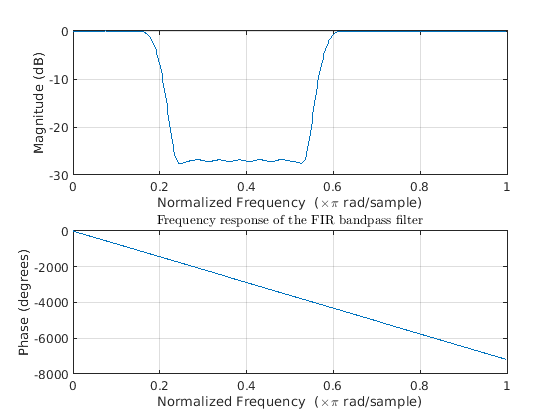

[b,a] = FirBandpass(... 
0.2139,... % lower cutoff frequency
0.5853,... % upper cutoff frequency
  -27,... % pass band gain
  160);   % length of the filter
figure();freqz(b,a); title("Frequency response of the FIR bandpass filter",'Interpreter',"latex");

The filter can be applied to music files:

[s,fs] = audioread("sounds/scrambled_eggs_5s.wav");

s_f = filter(b,a,s(1:(5*fs))); % filter the signal
s_f_r = 1/max(s_f) * s_f; % normalize the signal
sound(s_f_r,fs)

An attempt of using blockprocessing was made. 

The implementation uses the filter function which truncates the output signal to the length of the longest input signal. Therefore all overlaps between blocks was ignored. Having overlaps could have been achieved using the conv function instead.

Furthermore, the code is passed directly to an execution engine and does not consider a change in value of a variable until it is rerun. So the whole purpose of immediate feedback when changing the filter parameters is not possible either like this.

delta_t = 0.2 % time length of a block

delta_t = 0.2000

block_size = fs*delta_t % size of a block in samples

block_size = 8820

blocks = floor(length(s)/block_size) % number of complete blocks

blocks = 25

leftover = mod(length(s),block_size)

leftover = 0

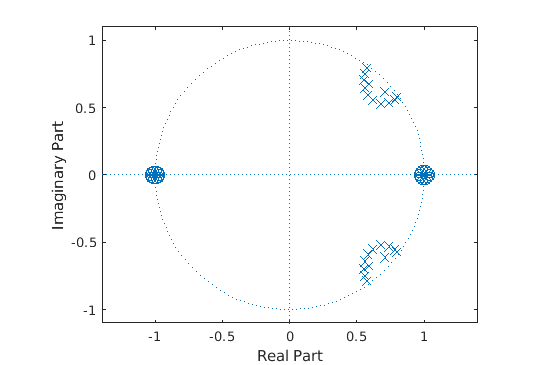

for blocknum = 1:blocks % iterate through all whole blocks
    tic; % start measuring processing time
    [b,a] = FirBandpass(0.3,0.5,-66,50); % create filter parameters
    sub_s = s((blocknum-1)*block_size+1:(blocknum)*block_size-1); % find block
    filtered = filter(b,a,sub_s); % filter block
    pause_t = delta_t - toc;
    pause(pause_t) % wait until the last sample has finished playing
    sound(filtered,fs);
end

% play the last block
sub_s = s((blocks)*block_size+1:(blocks)*block_size+leftover);
sound(filter(b,a,sub_s),fs);

#### Figures

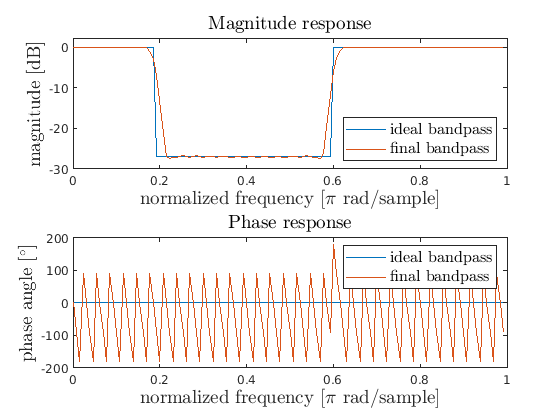

wc_lwr = 0.2; wc_upr = 0.6; G = -27; L = 260;
% calculate indices
idx_lwr = fix(wc_lwr*(L/2));
idx_upr = fix(wc_upr*(L/2));

% synthesize frequency response
Yhalf = ones(1,ceil((L/2)));
for i = idx_lwr:idx_upr
    Yhalf(i) = 10^(G/20);
end

% expand frequency response to the negative frequencies
if mod(L,2) == 0
    Y = [flip(Yhalf) Yhalf(2:end-1)];
else
    Y = [flip(Yhalf) Yhalf(2:end)];
end

% calculate impulse response
% and rearrange signal to have its peak in the center
% of the impulse response
h = fftshift(ifft(ifftshift(Y)));

% how much percent of the IR should be discarded?
cutfrac = 0.5; 

% create window
w = hamming(fix(L*(1-cutfrac)))';

% extract part of the impulse response to be windowed
sub_h = h(fix(cutfrac*1/2*L):fix(cutfrac*1/2*L)+fix((1-cutfrac)*L)-1);

% apply window
w_sig = w.*sub_h;



[Yfinal,~] = freqz(w_sig,1,length(Yhalf));
f = 0:1/length(Yhalf):1-1/length(Yhalf);

figure();
subplot(2,1,1); plot(f,20*log10(abs(Yhalf))); hold on; plot(f,20*log10(abs(Yfinal))); hold off; ylim([-30 2])
title("Magnitude response",'Interpreter',"latex",'FontSize', 14); xlabel("normalized frequency [$\pi$ rad/sample]",'Interpreter',"latex",'FontSize', 14); ylabel("magnitude [dB]",'Interpreter',"latex",'FontSize',14);
legend(["ideal bandpass" "final bandpass"],'Interpreter',"latex",'FontSize',12,'Location',"southeast")
subplot(2,1,2); plot(f,angle(Yhalf)*180/pi); hold on; plot(f,angle(Yfinal)*180/pi);hold off;
title("Phase response",'Interpreter',"latex",'FontSize', 14); xlabel("normalized frequency [$\pi$ rad/sample]",'Interpreter',"latex",'FontSize', 14); ylabel("phase angle [$^\circ$]",'Interpreter',"latex",'FontSize',14);
legend(["ideal bandpass" "final bandpass"],'Interpreter',"latex",'FontSize',12)
saveas(gcf,"plots/equalizer.pdf")

system(sprintf("pdfcrop plots%sequalizer.pdf plots%sequalizer.pdf",filesep,filesep));

PDFCROP 1.40, 2020/06/06 - Copyright (c) 2002-2020 by Heiko Oberdiek, Oberdiek Package Support Group.
==> 1 page written on `plots/equalizer.pdf'.


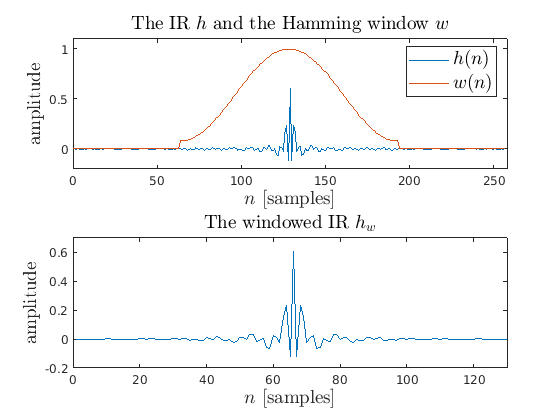

w_exp = [zeros(1,fix(cutfrac*1/2*L)-1) w zeros(1,fix(cutfrac*1/2*L)-1)];

figure();
subplot(2,1,1); plot(0:length(h)-1,h); hold on; plot(0:length(h)-1,w_exp); hold off; xlim([0 length(h)]); ylim([-0.2 1.1])
title("The IR $h$ and the Hamming window $w$",'Interpreter',"latex",'FontSize', 14); xlabel("$n$ [samples]",'Interpreter',"latex",'FontSize', 14); ylabel("amplitude",'Interpreter',"latex",'FontSize',14);
legend(["$h(n)$" "$w(n)$"],'Interpreter',"latex",'FontSize',14)
subplot(2,1,2); plot(w_sig); xlim([0 length(w_sig)]); ylim([-0.2 0.7])
title("The windowed IR $h_w$",'Interpreter',"latex",'FontSize', 14); xlabel("$n$ [samples]",'Interpreter',"latex",'FontSize', 14); ylabel("amplitude",'Interpreter',"latex",'FontSize',14);
saveas(gcf,"plots/equalizer_ir.pdf")

system(sprintf("pdfcrop plots%sequalizer_ir.pdf plots%sequalizer_ir.pdf",filesep,filesep));

PDFCROP 1.40, 2020/06/06 - Copyright (c) 2002-2020 by Heiko Oberdiek, Oberdiek Package Support Group.
==> 1 page written on `plots/equalizer_ir.pdf'.


function [b,a] = FirBandpass(wc_lwr,wc_upr,G,L)
    % calculate indices
    idx_lwr = fix(wc_lwr*(L/2));
    idx_upr = fix(wc_upr*(L/2));
    
    % synthesize frequency response
    Y = ones(1,ceil((L/2)));
    for i = idx_lwr:idx_upr
        Y(i) = 10^(G/20);
    end
    
    % expand frequency response to the negative frequencies
    if mod(L,2) == 0
        Y = [flip(Y) Y(2:end-1)];
    else
        Y = [flip(Y) Y(2:end)];
    end
    
    % calculate impulse response
    % and rearrange signal to have its peak in the center
    % of the impulse response
    h = fftshift(ifft(ifftshift(Y)));
    
    % how much percent of the IR should be discarded?
    cutfrac = 0.5; 
    
    % create window
    w = hamming(fix(L*(1-cutfrac)))';
    
    % extract part of the impulse response to be windowed
    sub_h = h(fix(cutfrac*1/2*L):fix(cutfrac*1/2*L)+fix((1-cutfrac)*L)-1);
    
    % apply window
    w_sig = w.*sub_h;
    
    % since we have a FIR filter b=IR
    b=w_sig;
    a=1;
end